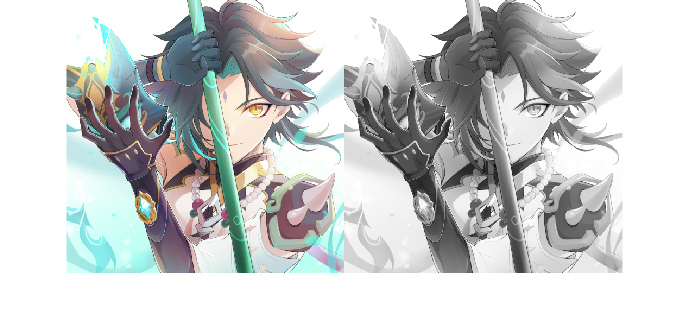

im = imread("yaksha.jpg");
img = rgb2gray(im);
imshowpair(im, img, "montage");

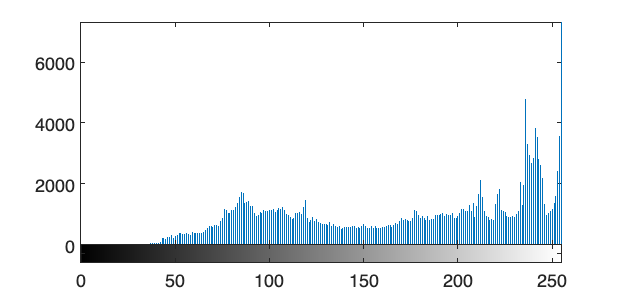

imhist(img);

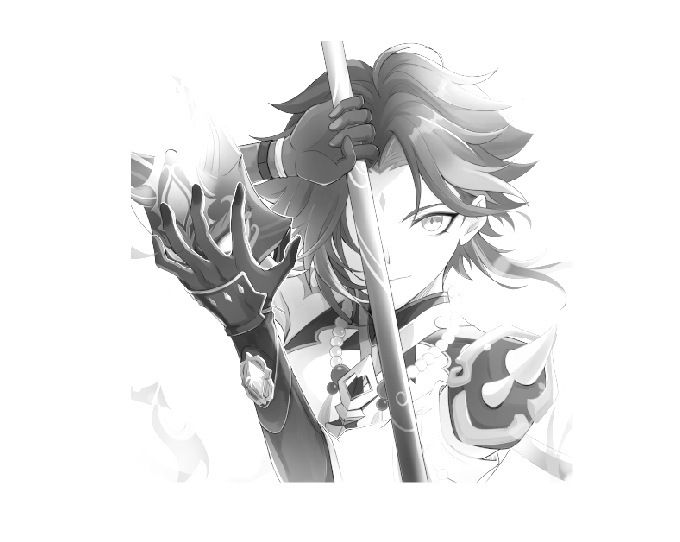

A = 1.2;
B = 0;
imy = img * A + B;
imshow(imy);

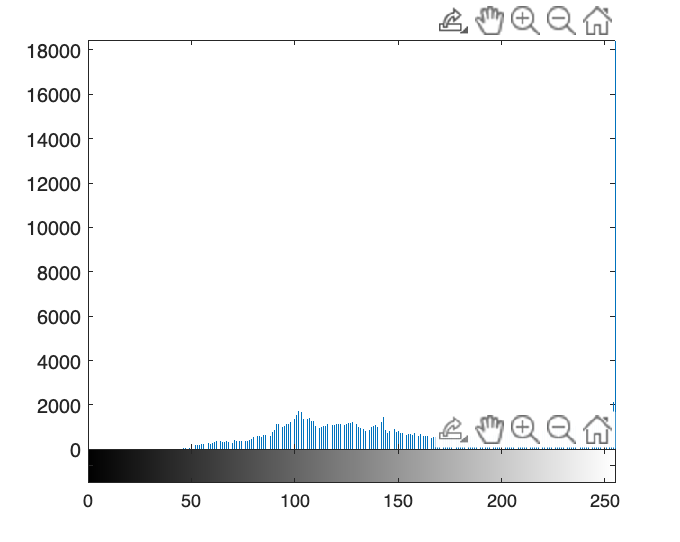

imwrite(imy, "12+0.jpg")
imhist(imy);

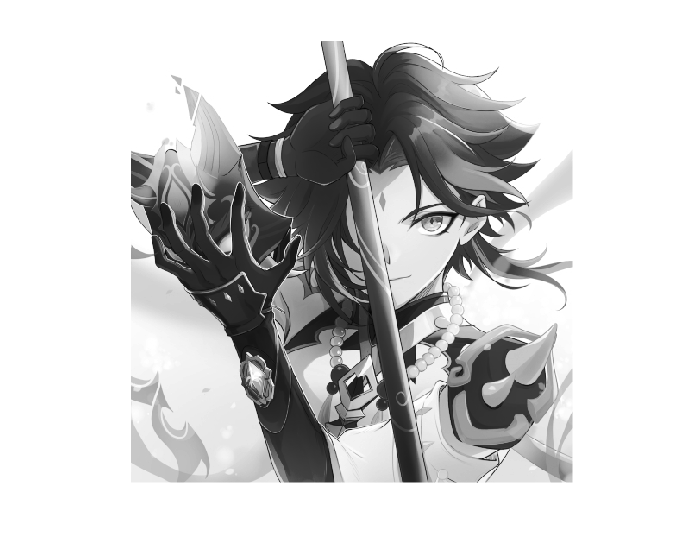

a = 128;
b = 160;
Mf = 255;
c = 64;
d = 128;
Mg = 255;

img = double(img);

img_ = (img * (c / a)) .* (0 <= img & img < a) ...
    + ((d - c) * (img - a) / (b - a) + c) .* (a <= img & img < b) ...
    + ((Mg - d) * (img - b) / (Mf - b) + d) .* (b <= img & img < Mf) ...
    + img .* (Mf <= img);

img_ = uint8(img_);
imshow(img_);

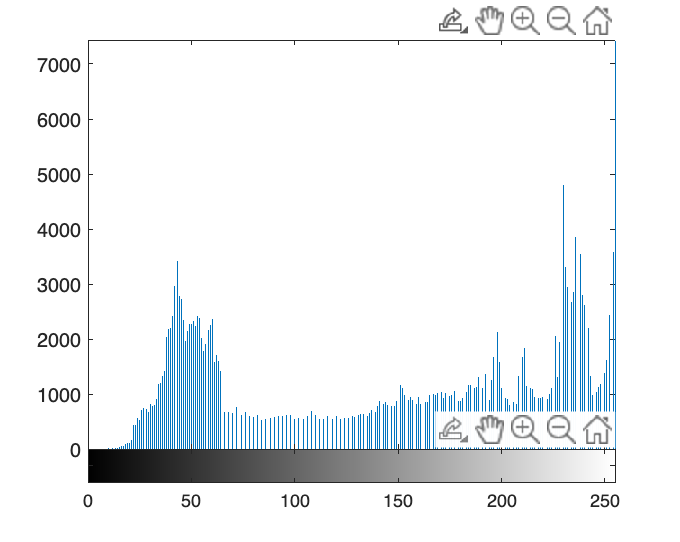

imwrite(img_, "fenduan.jpg")
imhist(img_);

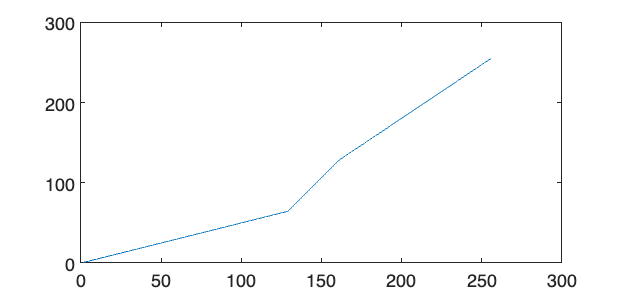

a = 128;
b = 160;
Mf = 255;
c = 64;
d = 128;
Mg = 255;

img = 0.:255;

img_ = (img * (c / a)) .* (0 <= img & img < a) ...
    + ((d - c) * (img - a) / (b - a) + c) .* (a <= img & img < b) ...
    + ((Mg - d) * (img - b) / (Mf - b) + d) .* (b <= img & img < Mf) ...
    + img .* (Mf <= img);
plot(img_)